clc
clf
clear all

function a = vectmath(c,m,d)
%c = complex number(A+jB), m = multiplier, d equals angle addition (+ or -)
    a = (abs(c)*m*cosd(rad2deg(angle(c))+d)) + j*(abs(c)*m*sind(rad2deg(angle(c))+d));
end

function a = pol2rec(mag,ang)
    a = mag*cosd(ang)+j*mag*sind(ang)
end

function x = polardisp(b)
    x = [num2str(round(abs(b),2)),'∠',num2str(round(rad2deg(angle(b)),2)),'°'];
end

## Graphs


%Load
% nexttile
% zvect([Vabs,Vbcs,Vcas, ...
% Vabps,Vbcps,Vcaps, ...
% Iall,Ibll,Icll])
% title('Load')
% %Source
% nexttile
% zvect([Val,Vbl,Vcl, ...
% Vabps,Vbcps,Vcaps, ...
% Iall,Ibll,Icll])
% title('Source')

## GUI

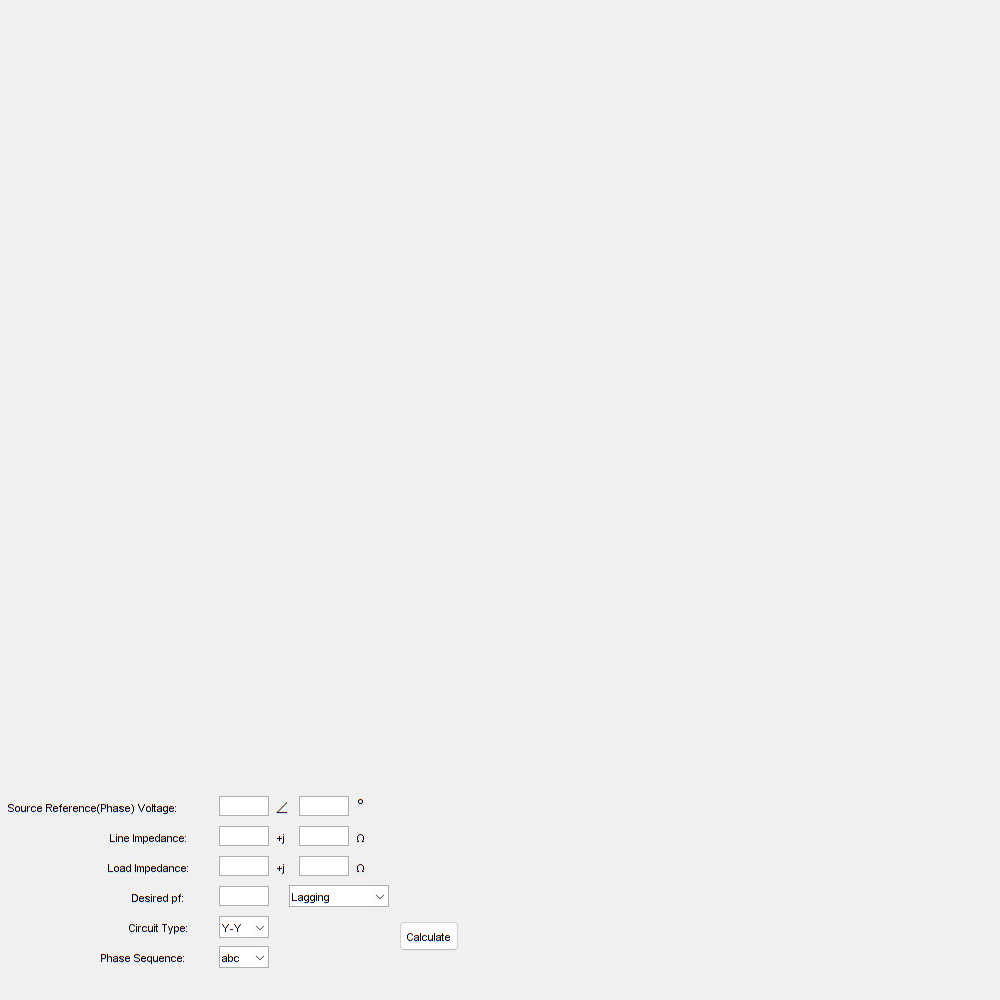

gui

function gui

    figure('Position', [100, 100, 1000, 1000]);
    Text = uicontrol('Style','text','string','Source Reference(Phase) Voltage:');
    Text.Position = [0 180 188 20];
    SRVabs = uicontrol('Style','edit'); %Source Referrence Voltage Magnitude
    SRVabs.Position = [220 185 50 20];
    Text = uicontrol('Style','text','string','∠','FontSize',14);
    Text.Position = [270 187 25 20];
    SRVang = uicontrol('Style','edit'); %Source Referrence Voltage Angle
    SRVang.Position = [300 185 50 20];
    Text = uicontrol('Style','text','string','°','FontSize',14);
    Text.Position = [350 187 25 20];
    
    Text = uicontrol('Style','text','string','Line Impedance:');
    Text.Position = [0 150 300 20];
    Xliner = uicontrol('Style','edit'); %Line Impedance Real
    Xliner.Position = [220 155 50 20];
    Text = uicontrol('Style','text','string','+j');
    Text.Position = [270 150 25 20];
    Xlinei = uicontrol('Style','edit'); %Line Impedance Imaginary
    Xlinei.Position = [300 155 50 20];
    Text = uicontrol('Style','text','string','Ω');
    Text.Position = [350 150 25 20];
    
    Text = uicontrol('Style','text','string','Load Impedance:');
    Text.Position = [0 120 300 20];
    Xloadr = uicontrol('Style','edit'); %Load Impedance Real
    Xloadr.Position = [220 125 50 20];
    Text = uicontrol('Style','text','string','+j');
    Text.Position = [270 120 25 20];
    Xloadi = uicontrol('Style','edit'); %Load Impedance Imaginary
    Xloadi.Position = [300 125 50 20];
    Text = uicontrol('Style','text','string','Ω');
    Text.Position = [350 120 25 20];
    
    Text = uicontrol('Style','text','string','Desired pf:');
    Text.Position = [125 90 70 20];
    Dpf = uicontrol('Style','edit'); %desired power factor
    Dpf.Position = [220 95 50 20];
    Dpfl = uicontrol('Style','popupmenu','String',['Lagging';'Leading']); %lagging/leading
    Dpfl.Position = [290 96 100 20];
    
    Text = uicontrol('Style','text','string','Circuit Type:');
    Text.Position = [125 60 70 20];
    Circuit = uicontrol('Style','popupmenu','String',['Y-Y';'Y-Δ';'Δ-Y';'Δ-Δ']);
    Circuit.Position = [220 65 50 20];
    
    Text = uicontrol('Style','text','string','Phase Sequence:');
    Text.Position = [100 30 90 20];        
    Phasesequenceo = uicontrol('Style','popupmenu','String',['abc';'cba']); %phase sequence is abc or cba, refers to the order that the phases are listed in.
    Phasesequenceo.Position = [220 35 50 20];
    % NEED TO ADD SHOWWORK BUTTON
    
    Calculateo = uicontrol('Style','pushbutton','String','Calculate', ...
        'Callback',@Calculate); %phase sequence is abc or cba, refers to the order that the phases are listed in.
    Calculateo.Position = [400 50 60 30];

## Calc Function

    function Calculate(object,event)
        SRVComplex = pol2rec(str2num(SRVabs.String),str2num(SRVang.String));
        Zline = str2num(Xliner.String)+j*str2num(Xlinei.String);
        Zload = str2num(Xloadr.String)+j*str2num(Xloadi.String);
        if Circuit.Value == 1 %Y-Y Case
            %Vphase Source
            Vaps = SRVComplex
            Vbps = vectmath(Vaps,1,-120)
            Vcps = vectmath(Vaps,1,+120)
            %Vline
            Vab = vectmath(Vaps,sqrt(3),+30)
            Vbc = vectmath(Vbps,sqrt(3),+30)
            Vca = vectmath(Vcps,sqrt(3),+30)
            %Vphase Load
            Vapl = vectmath(Vab,1/sqrt(3),-30)
            Vbpl = vectmath(Vbc,1/sqrt(3),-30)
            Vcpl = vectmath(Vca,1/sqrt(3),-30)
            %Line Currents 
            Ialine = Vaps/(Zload+Zline)
            Ibline = vectmath(Ialine,1,-120)
            Icline = vectmath(Ialine,1,+120)
            %Phase Currents Load
            Iapl = Ialine
            Ibpl = Ibline
            Icpl = Icline
            %Phase Current Source
            Iaps = Ialine
            Ibps = Ibline
            Icps = Icline           
        elseif Circuit.Value == 2 %Y-Δ Case
            %Vphase
            Vaps = SRVComplex
            Vbps = vectmath(Vaps,1,-120)
            Vcps = vectmath(Vaps,1,+120)
            %Vline
            Vab = vectmath(Vaps,sqrt(3),+30)
            Vbc = vectmath(Vaps,sqrt(3),+30)
            Vca = vectmath(Vaps,sqrt(3),+30)
            %Vphase Load
            Vapl = Vab
            Vbpl = Vbc
            Vcpl = Vca
            %Phase Currents Load
            Iapl = Vapl/Zload
            Ibpl = Vbpl/Zload
            Icpl = Vcpl/Zload
            %Line Currents
            Ialine = vectmath(Iapl,sqrt(3),-30)
            Ibline = vectmath(Ibpl,sqrt(3),-30)
            Icline = vectmath(Icpl,sqrt(3),-30)
            %Phase Current Source
            Iaps = Ialine
            Ibps = Ibline
            Icps = Icline
        elseif Circuit.Value == 3 %Δ-Y Case
            %Vphase Source
            Vaps = SRVComplex
            Vbps = vectmath(Vaps,1,-120)
            Vcps = vectmath(Vaps,1,+120)
            %Vline
            Vab = Vaps
            Vbc = Vbps
            Vca = Vcps
            %Phase Currents Load
            Iapl = Vab/Zload
            Ibpl = Vbc/Zload
            Icpl = Vca/Zload
            %line currents
            Ialine = Iapl
            Ibline = Ibpl
            Icline = Icpl
            %Phase Current Source
            Iaps = Vab/Zload
            Ibps = Vbc/Zload
            Icps = Vca/Zload
        elseif Circuit.Value == 4 %Δ-Δ Case
            %Vphase Source
            Vab = SRVComplex
            Vbc = vectmath(Vab,1,-120)
            Vca = vectmath(Vab,1,+120)
            %Vline
            Vaps = Vab
            Vbps =Vbc
            Vcps = Vca
            %phase currents Load
            Iapl = Vab/Zload
            Ibpl = vectmath(Iapl,1,-120)
            Icpl = vectmath(Iapl,1,+120)
            %line Current
            Ialine = vectmath(SRVComplex,1/sqrt(3),-30)/(Zload/3)
            Ibline = vectmath(Ialine,1,-120)
            Icline = vectmath(Ialine,1,+120)
            %Phase Current Source
            Iaps = Vab/Zload
            Ibps = Vbc/Zload
            Icps = Vca/Zload
        end
        %Power Calculations
        thetapf = rad2deg(angle(Vapl)-angle(Iapl))
        pf = cosd(thetapf)
        thetapfload = rad2deg(angle(Zload*Iaps)-angle(Iapl))
        pfload = cosd(thetapfload)
        P = 3*norm(Vapl)*norm(Iapl)*cosd(thetapf)
        Q = 3*norm(Vapl)*norm(Iapl)*sind(thetapf)
        S = 3*norm(Vapl)*norm(Iapl)
        
%ADD PF CORRECTION CALCULATION("To correct PF to 0.80 Lagging, add a
%15.245uF Capacitor
        Qload = 3*norm(Zload*Iaps)*norm(Iaps)*sind(thetapfload)
        Qadjusted = 3*norm(Zload*Iaps)*norm(Iaps)*sind(acosd(str2num(Dpf.String)))
        if Dpfl.Value == 2
            Qadjusted = Qadjusted * -1
            dpfltext = 'Leading'
        else
            dpfltext = 'Lagging'
        end
        Qchange = Qadjusted - Qload
        
        if Qchange >= 0
            LorC = [(norm(Zload*Iaps)^2)/(2*pi*60*abs(Qchange))]
            LorCText = ['An inductor of ',num2str(LorC),' H will correct the LOAD pf to ',Dpf.String,' ',dpfltext,'.']
        elseif Qchange < 0
            LorC = [abs(Qchange)/(2*pi*60*norm(Zload*Iaps)^2)*10^6]
            LorCText = ['A capicator of ',num2str(LorC),' µF will correct the LOAD pf to ',Dpf.String,' ',dpfltext,'.']
        end

        tiledlayout(4,4)
        nexttile([2,4])
        title("LOAD Power Triangle")
        Volt_Load = Zload*Iaps; %kV
        Start_S = S; %kVA - Apparant Load Power - S
        Start_PF = pfload; %Lagging - starting power factor
        Start_Theta = thetapfload;
        Start_P = P; % X Axis - P
        Start_Q = Qload; % Y Axis
        freq = 60; %hz

        Qc = Qchange;
        New_Q = Qadjusted; % X Axis - Reactive Power
        New_S = sqrt(New_Q.^2+Start_P.^2); %Apparent Power
        New_PF = str2num(Dpf.String);
        New_Theta = acosd(New_PF);
        line([0 Start_P],[0 0],'color','b') % P
            text(Start_P/2,50,['P=',num2str(round(Start_P,0)),' W'])
        line([Start_P Start_P],[0 Start_Q],'color','b') % Q
            text(Start_P,Start_Q*.9,['Q=',num2str(round(Start_Q,0)),' VAR'])
        line([0 Start_P],[0 Start_Q],'color','b') % S
            text(Start_P/2,Start_Q*.75,['S=',num2str(round(Start_S,0)),' VA'])

        text(50,30,['newθpf=', num2str(round(New_Theta,2)),'°     newpf=',num2str(New_PF)]) %New Theta
        text(0,100,['θpf=', num2str(round(Start_Theta,2)),'°     pf=',num2str(Start_PF)])
        
        line([Start_P Start_P],[0 New_Q],'color','r') % New_Q
            text(Start_P,New_Q*.9,['Qnew=',num2str(round(New_Q,0)),' VAR'])
        line([0 Start_P],[0 New_Q],'color','r') % New_S
            text(Start_P/2,New_Q*.75,['Snew=',num2str(round(New_S,0)),' VA'])
        if New_Q>=0
            axis([0 Start_P*1.2 0 Start_Q*1.2]) % Set the axis limits
        else
            axis([0 Start_P*1.2 New_Q*1.2 Start_Q*1.2]) %This is for negative
        end
        

## SOURCE TEXT


        Text = uicontrol('Style','text','string','SOURCE:','FontSize',12.5);
            Text.Position = [10 420 150 20];

        Text = uicontrol('Style','text','string',['V Phase (A) :',polardisp(Vaps)]);
            Text.Position = [10 390 150 20];
        Text = uicontrol('Style','text','string',['V Phase (B) :',polardisp(Vbps)]);
            Text.Position = [10 360 150 20];
        Text = uicontrol('Style','text','string',['V Phase (C) :',polardisp(Vcps)]);
            Text.Position = [10 330 150 20];

        Text = uicontrol('Style','text','string',['I Phase (A) :',polardisp(Iaps)]);
            Text.Position = [10 300 150 20];
        Text = uicontrol('Style','text','string',['I Phase (B) :',polardisp(Ibps)]);
            Text.Position = [10 270 150 20];
        Text = uicontrol('Style','text','string',['I Phase (C) :',polardisp(Icps)]);
            Text.Position = [10 240 150 20];


## LINE TEXT

        Text = uicontrol('Style','text','string','LINE:','FontSize',12.5);
            Text.Position = [180 420 150 20];

        Text = uicontrol('Style','text','string',['V Line (A) :',polardisp(Vab)]);
            Text.Position = [180 390 150 20];
        Text = uicontrol('Style','text','string',['V Line (B) :',polardisp(Vbc)]);
            Text.Position = [180 360 150 20];
        Text = uicontrol('Style','text','string',['V Line (C) :',polardisp(Vca)]);
            Text.Position = [180 330 150 20];
            
        Text = uicontrol('Style','text','string',['I Line (A) :',polardisp(Ialine)]);
            Text.Position = [180 300 150 20];
        Text = uicontrol('Style','text','string',['I Line (B) :',polardisp(Ibline)]);
            Text.Position = [180 270 150 20];
        Text = uicontrol('Style','text','string',['I Line (C) :',polardisp(Icline)]);
            Text.Position = [180 240 150 20];

## LOAD TEXT

        Text = uicontrol('Style','text','string','LOAD:','FontSize',12.5);
            Text.Position = [350 420 150 20];

        Text = uicontrol('Style','text','string',['V Phase (A):',polardisp(Vapl)]);
            Text.Position = [350 390 150 20];
        Text = uicontrol('Style','text','string',['V Phase (B):',polardisp(Vbpl)]);
            Text.Position = [350 360 150 20];
        Text = uicontrol('Style','text','string',['V Phase (C):',polardisp(Vcpl)]);
            Text.Position = [350 330 150 20];

        Text = uicontrol('Style','text','string',['I Phase (A) :',polardisp(Iapl)]);
            Text.Position = [350 300 150 20];
        Text = uicontrol('Style','text','string',['I Phase (B) :',polardisp(Ibpl)]);
            Text.Position = [350 270 150 20];
        Text = uicontrol('Style','text','string',['I Phase (C) :',polardisp(Icpl)]);
            Text.Position = [350 240 150 20];


## Extra Text

        Text = uicontrol('Style','text','string',['Voltage Drop Load Impedance (A):',polardisp(Zload*Iaps)]);
            Text.Position = [630 390 300 20];
        Text = uicontrol('Style','text','string',['Voltage Drop Load Impedance (B):',polardisp(Zload*Ibps)]);
            Text.Position = [630 360 300 20];
        Text = uicontrol('Style','text','string',['Voltage Drop Load Impedance (C):',polardisp(Zload*Icps)]);
            Text.Position = [630 330 300 20];

        Text = uicontrol('Style','text','string',['Voltage Drop Line Impedance (A):',polardisp(Zline*Iaps)]);
            Text.Position = [630 300 300 20];
        Text = uicontrol('Style','text','string',['Voltage Drop Line Impedance (B):',polardisp(Zline*Ibps)]);
            Text.Position = [630 270 300 20];
        Text = uicontrol('Style','text','string',['Voltage Drop Line Impedance (C):',polardisp(Zline*Icps)]);
            Text.Position = [630 240 300 20];

        Text = uicontrol('Style','text','string',[LorCText]);
            Text.FontSize = 11.5;
            Text.Position = [230 475 600 20];

    end
end
